% BLock great
P = imread("C:\Users\Liushoukang\Desktop\VMIE\image\misc\7.1.01.tiff");

P=double((P));

[X,Y,Z,T]=KeyGen(P,2,1.2,-2);

[B1,B2,B3,B4]=Block(P);

[H,N]=size(B1);

Phi1=PartHadamardMtx(H,N);
Phi2=PartHadamardMtx(H,N);

Rx1=X(1:H*CR);Rx2=X(1:N);
Ry1=Y(1:H*CR);Ry2=Y(1:N);

[~,Rx1Index]=sort(Rx1);
[~,Rx2Index]=sort(Rx2);
[~,Ry1Index]=sort(Ry1);
[~,Ry2Index]=sort(Ry2);

[~,Index]=sort(Z(1:H*N*CR*CR));

Phi1=Phi1(Rx1Index,Rx2Index);
Phi2=Phi2(Ry1Index,Ry2Index);

RBI=Quantization(Z(1:H*N),255);

RBI=reshape(S(RBI,H*N),H,N);

[B10,Max1,Min1]=CS(B1,Phi1,Phi2,Index,RBI);

[B20,Max2,Min2]=CS(B2,Phi1,Phi2,Index,RBI);

[B30,Max3,Min3]=CS(B3,Phi1,Phi2,Index,RBI);

[B40,Max4,Min4]=CS(B4,Phi1,Phi2,Index,RBI);

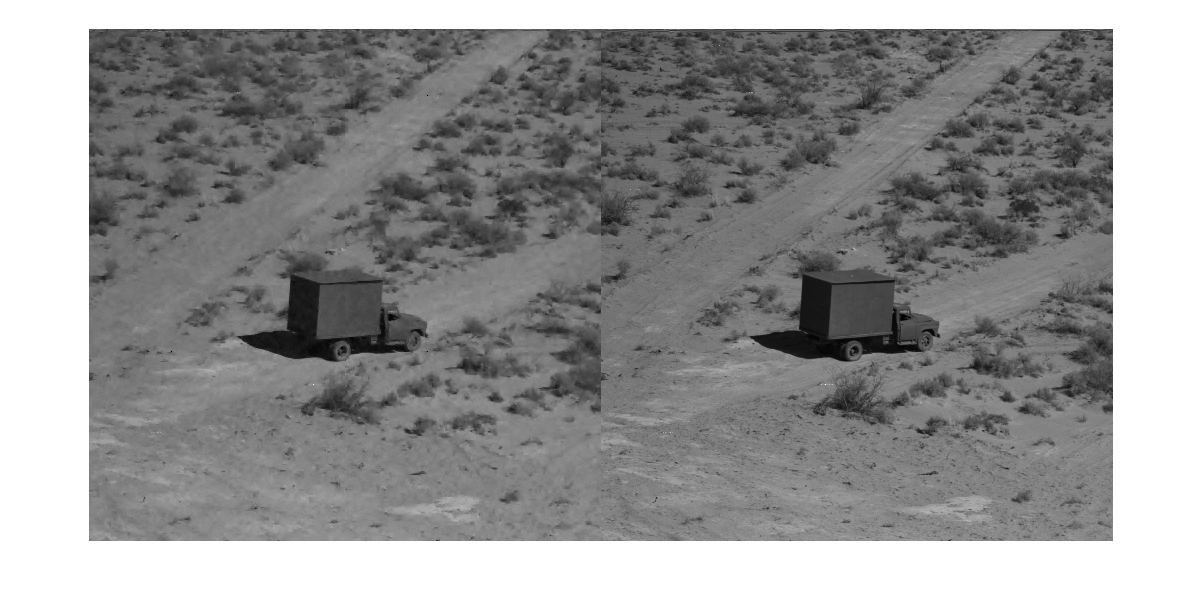

ans = 32.4231

ans = 45.4190

ans = single
0.9986

ans = 1

ans = 45.4190

ans = 32.1249

B11=ICS(B10,Max1,Min1,Phi1,Phi2,Index,RBI);

B22=ICS(B20,Max2,Min2,Phi1,Phi2,Index,RBI);

B33=ICS(B30,Max3,Min3,Phi1,Phi2,Index,RBI);

B44=ICS(B40,Max4,Min4,Phi1,Phi2,Index,RBI);

reconstructed_image = [B11,B22;B33,B44];